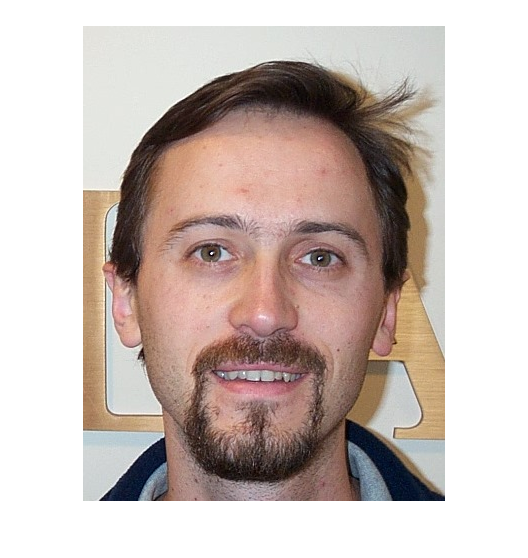

image = imread("Images/DB1/db1_06.jpg");

imshow(image)

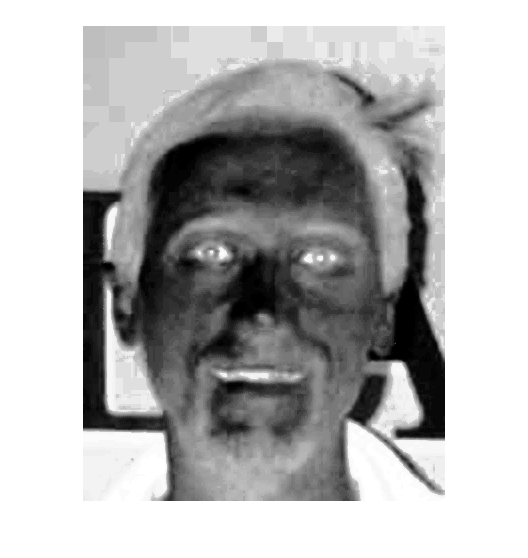


%image = im2double(image);
image = im2uint8(image);


rCbCr = rgb2ycbcr(image);

Y = rCbCr(:,:,1);
Cb = rCbCr(:,:,2);
Cr = rCbCr(:,:,3);

% Calculate Cb^2
dCb = double(Cb);
CbPow = power(dCb,2);

% Normalize Cb^2 to range between 0 and 255
normCbPow = CbPow./max(max(CbPow));
CbPow = normCbPow.*255;

% Calculate the negative of Cr
CrNeg = 255 - Cr;

% Calculate CrNeg^2
dCrNeg = double(CrNeg);
CrNegPow = power(dCrNeg,2);

% Normalize the negative of Cr between 0 and 255
normCrNegPow = CrNegPow./max(max(CrNegPow));
CrNegPow = normCrNegPow.*255;
% Calculate Cb/Cr
CbDivCr = double(Cb)./double(Cr);

% Normalize Cb/Cr between 0 and 255
normCbDCr = CbDivCr./max(max(CbDivCr));
CbDCrFinal = normCbDCr.*255;

% Calculate eyeMapC
eyeMapC = (1/3).*CbPow + (1/3).*CrNegPow + (1/3).*CbDCrFinal;

eyeMapC = histeq(uint8(eyeMapC));
imshow(eyeMapC)

eyeMapC = im2double(eyeMapC)

eyeMapC =      7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.450980392156863e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01     7.607843137254902e-01  

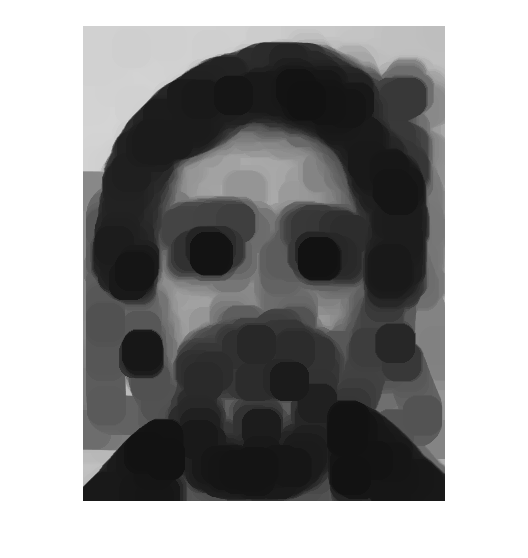

%eyemapC = im2double(eyeMapC);

 % Structuring element for dilation and erosion
SE_height = round(length(Y(:,1))/24);

SE = strel('disk',SE_height,8);

% Erosion of the luma component
erosion = imerode(Y,SE);
erosion = erosion + 1;

imshow(erosion)